clc
clear all

scale = 0.482430503/0.7; % 0.4626
ff = 7.7918; % 8.0840
alpha = deg2rad(79.3549/2); %input in deg 79.8571
beta = alpha;  %input in deg

R = 8.55*(scale) %mm

R = 5.8925

a = 10.5*(scale) %found by reducing or increasing such that gammamax - gammamin = alpha + beta

a = 7.2365

b = 13.2*(scale)

b = 9.0973

H = 45.86*(scale)

H = 31.6061

C = 4.25*(scale)

C = 2.9290


x = 4;
i = 0;

a1 = 0.9449;
b1 = 50.42;
c1 = -0.08977;
a2 = 0.9526;
b2 = 1.74;
c2 = 2.857;
a3 = 0.1678;
b3 = 103.3;
c3 = 0.629;

% a1 = 0.9449;
% b1 = 50.42;
% c1 = -0.08977;
% a2 = 0.9526;
% b2 = 1.74;
% c2 = 2.857;
% a3 = 0.1678;
% b3 = 103.3;
% c3 = 0.629;
% a1*sin(b1*x+c1) + a2*sin(b2*x+c2) + a3*sin(b3*x+c3)

for theta = 0:0.1:(2*pi)
    i = i+1;
    A = H - R*((sqrt((x^2)-(sin(theta))^2)) + cos(theta));
    epsilon = atan(A/C);
    zeta(i) = epsilon;
    f = acos(((A^2) + (C^2) - (a^2) - (b^2))/(-2*a*b));
    g = b*sin(f)/(sqrt((C^2) + A^2));
    %gamma = alpha - ((atan((H -R*((sqrt(x^2 - (sin(theta))^2) + cos(theta))))/C)) - asin(b*sin(acos((H -R*((sqrt(x^2 - (sin(theta))^2) + cos(theta))) + (C^2) - (a^2) - (b^2)))/(-2*a*b))/(sqrt((C^2)+ (H -R*((sqrt(x^2 - (sin(theta))^2) + cos(theta)))^2)))))
    gamma(i) = alpha - (zeta(i) - g);
    t(i) = theta/(2*pi*ff);
    L(i) = a1*sin(b1*t(i) + c1) + a2*sin(b2*t(i) + c2) + a3*sin(b3*t(i) + c3);
    m = 2*(sqrt((x^2) - (sin(theta))^2));
    n(i) = b*(sqrt(1 - ((C - a*cos(alpha - gamma(i)))/b)^2));
    o(i) = a*(C - a*cos(alpha - gamma(i)))*sin(alpha - gamma(i));
    e = R*(((sin(2*theta))/m) + sin(theta));
    w(i) = a*cos(alpha - gamma(i));
    gammadot(i) = 2*pi*ff*e/((o(i)/n(i)) - w(i));
    tau(i) = 0.47*L(i)*990*gammadot(i)/(2*(2*pi*ff));
end

gammamax = rad2deg(max(gamma))

gammamax = 57.6116

gammamin = rad2deg(min(gamma))

gammamin = -6.9676

mingammarad = min(gamma)

mingammarad = -0.1216


angle = (gammamax - gammamin)

angle = 64.5792


stnumber =(ff*0.482430503*sin((deg2rad(angle/2))))/8

stnumber = 0.2510

zetamax = max(zeta);
zetamin = min(zeta);
zetamax - zetamin

ans = 0.7317

disp("zeta min should be 40 or more")

zeta min should be 40 or more


rad2deg(zetamin)

ans = 36.1953

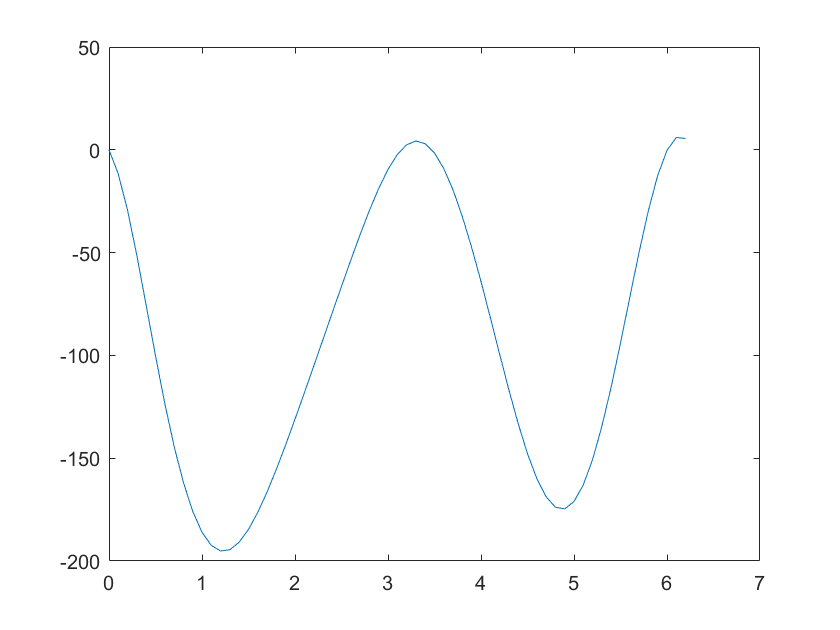

plot(0:0.1:(2*pi),tau);

p = (2*pi*ff)*(tau)/1000

p =          0   -0.5755   -1.4453   -2.5222   -3.7066   -4.9049   -6.0405   -7.0580   -7.9208   -8.6072   -9.1074   -9.4206   -9.5540   -9.5215   -9.3419   -9.0374   -8.6313   -8.1467   -7.6044   -7.0222   -6.4139   -5.7899   -5.1574   -4.5210   -3.8842   -3.2507   -2.6262   -2.0195   -1.4441   -0.9188   -0.4666   -0.1125    0.1192    0.2092    0.1454   -0.0753   -0.4478   -0.9597   -1.5935   -2.3274   -3.1361   -3.9918   -4.8636   -5.7185   -6.5214   -7.2362   -7.8273   -8.2615   -8.5102   -8.5518


plot(0:0.1:(2*pi),abs(p));
p_max = (2*pi*ff)*max(abs(tau))/1000   

p_max = 9.5540

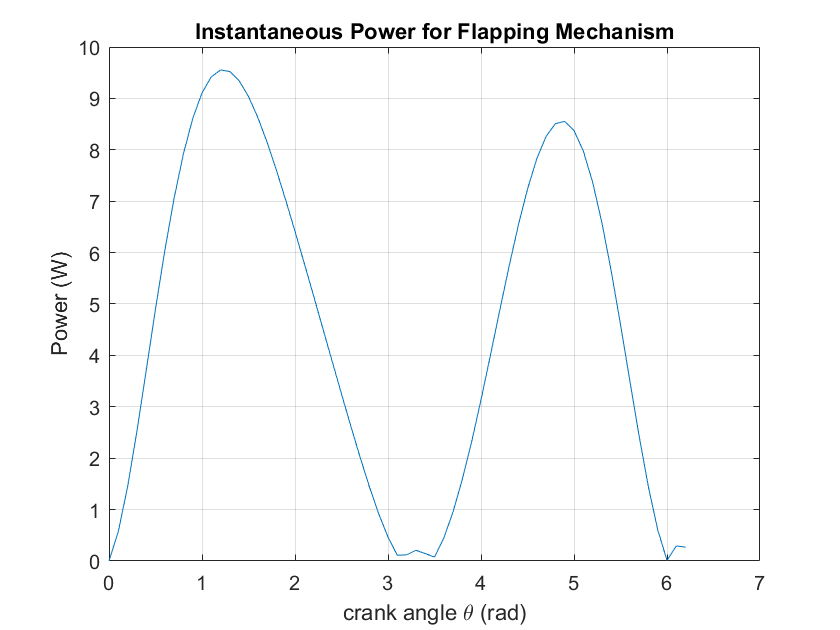

title('Instantaneous Power for Flapping Mechanism')
xlabel('crank angle \theta (rad)')
ylabel('Power (W)')
grid on 


max(abs(tau))

ans = 195.1500

p_abs = abs(p)

p_abs =          0    0.5755    1.4453    2.5222    3.7066    4.9049    6.0405    7.0580    7.9208    8.6072    9.1074    9.4206    9.5540    9.5215    9.3419    9.0374    8.6313    8.1467    7.6044    7.0222    6.4139    5.7899    5.1574    4.5210    3.8842    3.2507    2.6262    2.0195    1.4441    0.9188    0.4666    0.1125    0.1192    0.2092    0.1454    0.0753    0.4478    0.9597    1.5935    2.3274    3.1361    3.9918    4.8636    5.7185    6.5214    7.2362    7.8273    8.2615    8.5102    8.5518


mean(p_abs)

ans = 4.5459